# Sampling LTI Systems: a few Examples

## Introduction

In this live script, we consider some continuous-time LTI systems and wish to investigate the sampled signal representations of the same dynamic systems as the sampling period varies. In particular, we would like to be able to answer the following questions:

- How does the sampled-time description correlate with the continuous-time model?

- What happens if we increase or decrease the sampling rate? Does the sampled-time model change with the sampling time?

- Does the sampled-time model describe the behavior of the continuous-time dynamic system for any possible choice of the sampling time value?

## Automobile suspension system: a quarter-car model

From a real vehicle 

 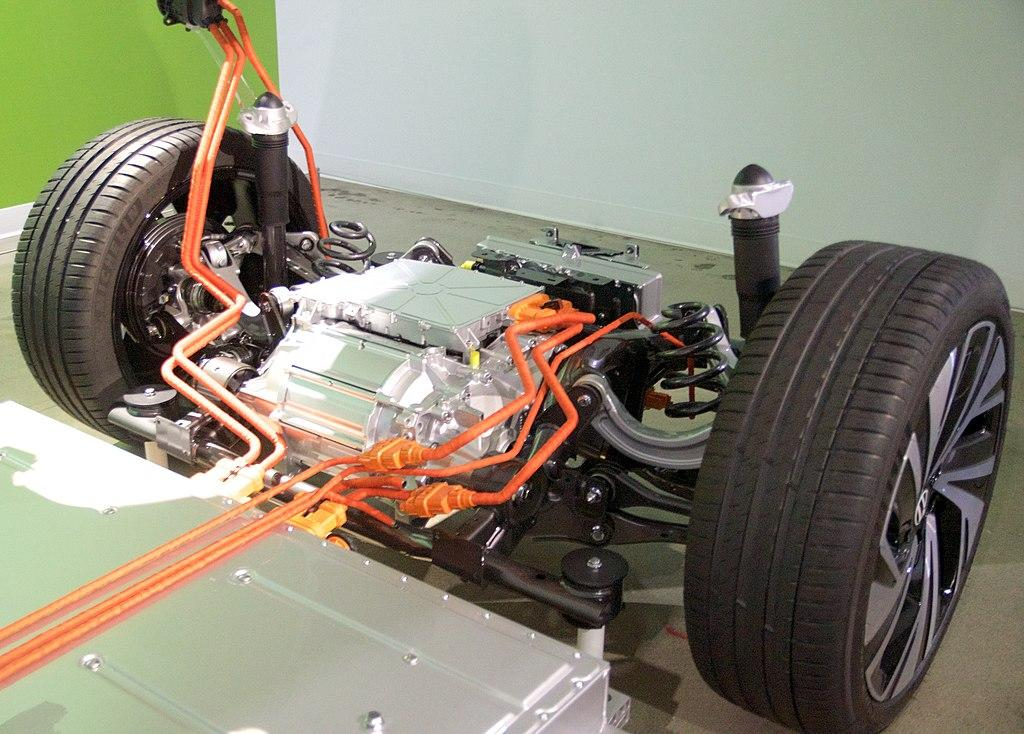

Volkswagen ID.3 rear wheels suspension (Source: Wikimedia)

to a simplified quarter-car model:

 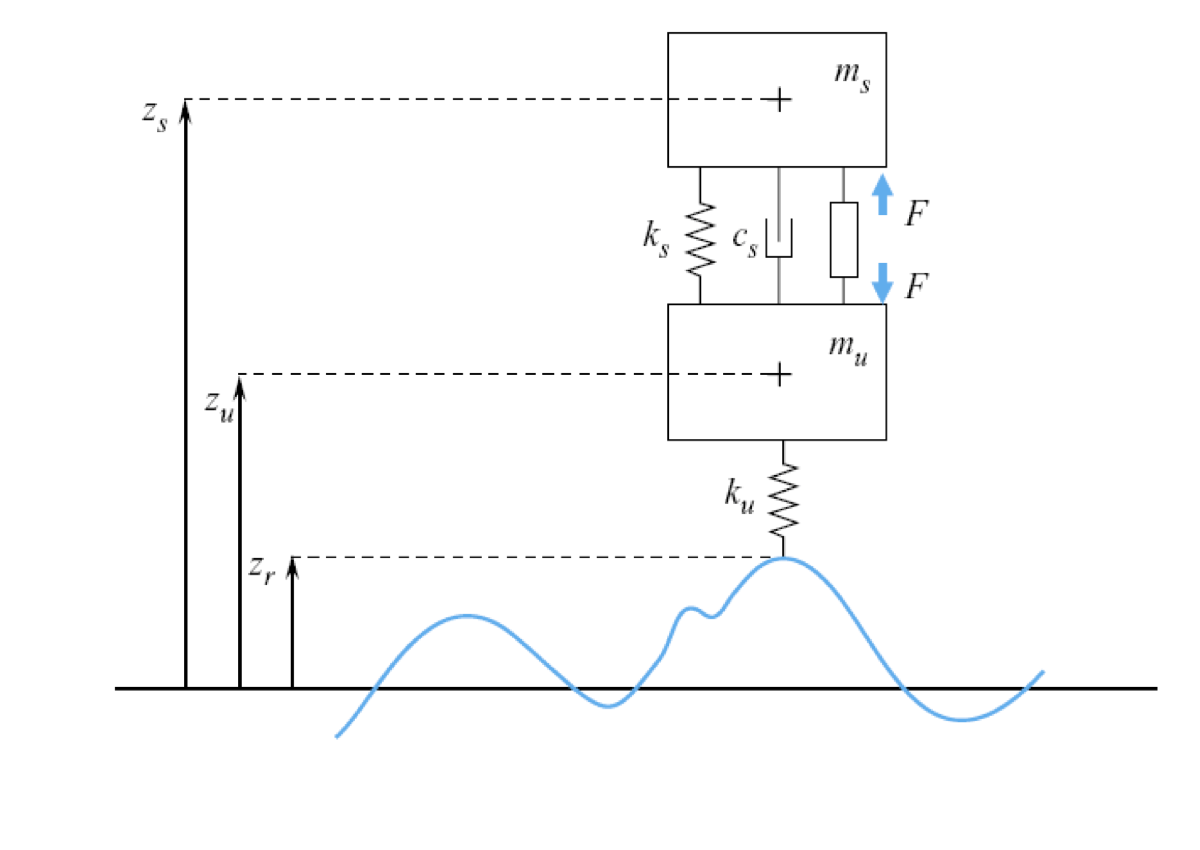

### Hypotheses of the quarter-car model:

- The vehicle is assumed to be an assembly of four decoupled parts;

- Each part consists of the sprung mass [i.e., a quarter of the vehicle mass, supported by a suspension actuator, placed between the vehicle and the tyre] and the unsprung mass [i.e., the wheel+tyre subassembly];

- The model allows only for vertical motion. The vehicle is moving forward at an almost constant speed. 

### The model


$$\[
 \left\{ 
\begin{array}{rcl}
  \left[\begin{array}{c} \dot{x}_1 \\ \dot{x}_2 \\ \dot{x}_3 \\ \dot{x}_4 \end{array} \right]&=& 
	 \left[ \begin{array}{cccc}
		0 & 0 & 1 & 0 \\[1 em]
		0 & 0 & 0 & 1 \\[1 em]
		\displaystyle \frac{k_s}{m_s} & \displaystyle\frac{k_s}{m_s} &\displaystyle -\frac{c_s}{m_s} & \displaystyle\frac{c_s}{m_s} \\[1 em]
		\displaystyle\frac{k_s}{m_u} &\displaystyle -\frac{k_s+k_u}{m_u} & \displaystyle\frac{c_s}{m_u} & \displaystyle -\frac{c_s}{m_u}
		\end{array} \right]  \cdot  \left[\begin{array}{c} x_1 \\ x_2 \\ x_3 \\ x_4 \end{array}\right] + 
		 \left[\begin{array}{cc} 0 & 0 \\[1 em] 0 & 0\\[1 em] 0 & \displaystyle\frac{1}{m_s} \\[1 em]\displaystyle\frac{k_s}{m_u} & \displaystyle-\frac{1}{m_u} \end{array} \right]
									\cdot \left[\begin{array}{c} u_1 \\ u_2 \end{array}\right] \\[2 ex]\\
		 \left[\begin{array}{c} y_1 \\ y_2  \end{array} \right] &=& 
			\left[\begin{array}{cccc}
				\displaystyle-\frac{k_s}{m_s} & \displaystyle\frac{k_s}{m_s} &\displaystyle -\frac{c_s}{m_s} &\displaystyle \frac{c_s}{m_s} \\[1 em]
				0 & k_u & 0 & 0
			\end{array} \right] \cdot \left[\begin{array}{c} x_1 \\ x_2 \\ x_3 \\ x_4 \end{array} \right] +
			\left[\begin{array}{cc}
				0 & \displaystyle\frac{1}{m_s} \\[1 em]
				-k_u & 0
				\end{array} \right] \cdot\left[\begin{array}{c} u_1 \\ u_2 \end{array}\right] 
\end{array}  \right.
\]
$$


Parameters:

- the sprung mass, i.e., a quarter of the vehicle mass $m_s$;

- the unsprung mass: the mass of one wheel $m_u$;

- the spring constant  $k_s$ of the passive suspension actuator; 

- the damping coefficient of the passive suspension damper $c_s$;

- the spring constant of the tyre $k_u$ 

Inputs:

- ground vertical position vs. the steady-state ground elevation [m];

- active actuator force [N].

Outputs:

- sprung mass vertical acceleration;

- contact force between the tyre and the ground.

State variables:

- vertical positions of sprung and unsprung masses vs. the corresponding steady-state values;

- vertical speeds of masses.


$$\left\{
\begin{array}{rcl}
	x_1(t) &=&  z_{s}(t)-\bar{z}_s \\
	x_2(t) &=&  z_{u}(t)-\bar{z}_u \\
	x_3(t) &=& \dot{x}_1(t)\\
	x_4(t) &=& \dot{x}_2(t)\\[1.5 ex]
	u_1(t) &=& z_{r}(t)-\bar{z}_{r}\\
	u_2(t) &=& F(t) \\[1.5 ex]
	y_1(t) &=& \ddot{x}_1(t) \\
	y_2(t) &=& k_u \left( x_2(t) - u_1(t) \right)
\end{array} \right.$$


### Reference

- Antsaklis  P. J.  & Michel  A. N. (2006). *Linear systems*. Birkhäuser.

### Initialisation 

% cleaning the Matlab workspace

close all
clear
clc

% and assigning the parameters
% 
mS = 375;   % [kg] sprung mass
mU = 30;    % [kg] unsprung mass
kS = 1500;  % [N/m] spring stiffness of the passive suspension system
kU = 6500;  % [N/m] spring stiffness of the tyre
cS = 1125;  % [N s/m] damping constant 

### The continuouus-time LTI system

% the matrices of the LTI system equations
matA = [   0           0      1     0   ;...
             0           0      0     1   ;...
          -kS/mS       kS/mS -cS/mS  cS/mS ;...
           kS/mU -(kS+kU)/mU  cS/mU -cS/mU];
       
matB = [   0      0  ;...
             0      0  ;...
             0     1/mS;...
           kU/mU  -1/mU];  
       
matC = [ -kS/mS    kS/mS   -cS/mS    cS/mS;...
              0       kU        0        0];
          
matD = [0 1/mS; -kU 0];

% let's create a continuous-time LTI system
LTI_q_carC = ss(matA, matB, matC, matD);

eig(matA) % the eigenvalues: they compare in the response modes of the free state movement

ans =  -32.8352 + 0.0000i
  -4.8820 + 0.0000i
  -1.3914 + 1.8629i
  -1.3914 - 1.8629i


There are two real negative eigenvalues and the others are conjugate complexes. If we consider the free state movement of the continuous time LTI system, the response modes contain two modes decaying exponentially to zero and two damped **sinusoids** with an angular frequency  $\bar{\Omega} \approx 1.8629\; \text{rad/s}$, i.e. with the period $\bar T \approx 3.3728 \; \text{s}$.

### Sampling the LTI system

Let's get a few **sampled time descriptions** of this LTI dynamic system. 

To explore the effects of sampling, we choose two different sampling periods: the first of relatively small value ( $T_1 \ll \bar T$ ) and the other one close to the free movement sinusoid period. Using each of them, we discretise the system, obtaining two sampled-time representations of the system. Evaluate the forced response to a unit step input (applied to both the inputs) of these discrete-time models, then compare the results with the outputs of the continuous-time model. 

% 1st sampling experiment
%
Ts1 = 1/20; % [s] - 20 samples per second

sysD1 = c2d(LTI_q_carC,Ts1); % <-- let's convert from continuous-time to sampled time LTI system
Ad1=sysD1.A; Bd1=sysD1.B;
Cd1=sysD1.C; Dd1=sysD1.D;
eig(Ad1) % the eigenvalues of the sampled system

ans =    0.1936 + 0.0000i
   0.9288 + 0.0868i
   0.9288 - 0.0868i
   0.7834 + 0.0000i


Compare the eigenvalues with those of the continuous-time system: again, there are two real eigenvalues (associated with modes that decay exponentially to zero) and two conjugate complexes, associated with damped oscillations.

% 2nd sampling experiment
%
Ts2 = 2.5; % [s]  very close to the period of the free state movement oscillations - 1 sample every 2.5 seconds (0.4 sample per second)
sysD2 = c2d(LTI_q_carC,Ts2); % <-- let's convert from continuous-time to sampled time LTI system
Ad2=sysD2.A; Bd2=sysD2.B;
Cd2=sysD2.C; Dd2=sysD2.D;
eig(Ad2) % the eigenvalues of the 2nd sampled system

ans =   -0.0017 + 0.0308i
  -0.0017 - 0.0308i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


If we compare this result with that obtained from the previous sampled-time description of the system, we note that the response modes with damped oscillations are present. However, the period of the oscillations is more significant than that obtained in the first example. 

### Graphical Comparison of the Step Responses

To better understand what happens when changing the sampling period, let us compare the unit step responses of the continuous-time system with those of the sampled-time representations.

% --- step inputs configuration ---
% let's configure the step inputs
%
% 1st input <-- ground vertical position vs. the steady-state ground
%               elevation [m] <--> an increment of 0.1 m
% 2nd input <-- active actuator force [N] <--> from 0 N to 10000 N
%
opt = stepDataOptions('StepAmplitude',[0.1, 10000]);
% ----------------------------------


% --- final time instant fo the step uoutputs evaluation
Tfinal = 5.5; % s

% --- step outputs evaluation ---
[Yc, Tc] = step(LTI_q_carC, Tfinal, opt);
[Yd1, Td1] = step(sysD1, Tfinal, opt);
[Yd2, Td2] = step(sysD2, Tfinal, opt);

lineStyles = zeros(3,3);
lineStyles(1,:) = [0 0.4470 0.7410];
lineStyles(2,:) = [0.8500 0.3250 0.0980];
lineStyles(3,:) = [0 1 0];
% three different plot colors [as RGB triplet]

% ------------------------------------------------------------
f_4ercar = figure('Name','quarter car model step responses', ...
         'Units','normalized', 'Position', [0, 0, 0.80, 0.90]);

subplot(2,2,1); % <-- from input u1 to output y1

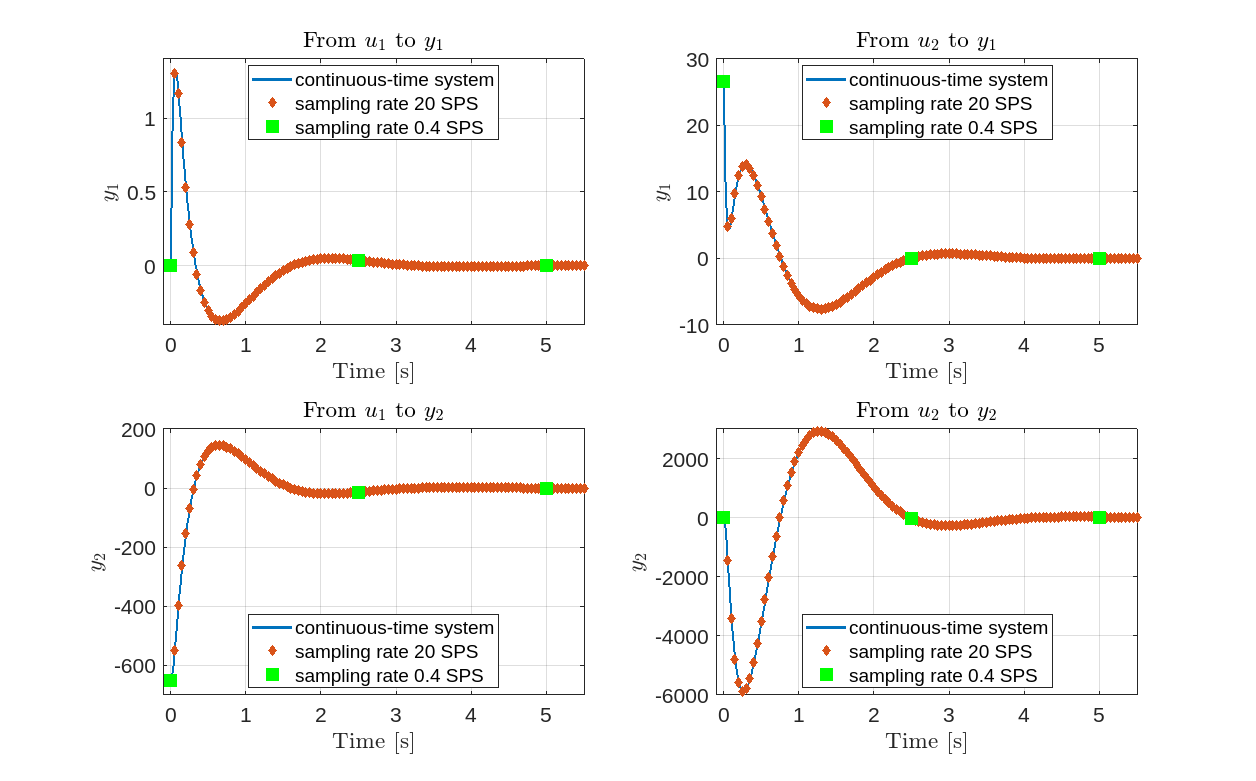

plot(Tc, Yc(:,1,1),'-','Color',lineStyles(1,:),'LineWidth',2.0); 
% the continuous-time step output 
hold on;
plot(Td1,Yd1(:,1,1), 'LineStyle','none', 'Marker','diamond',...
    'MarkerSize',6.0, 'MarkerFaceColor',lineStyles(2,:),...
    'MarkerEdgeColor',lineStyles(2,:)); % step response of the 1st discrete time model
plot(Td2, Yd2(:,1,1),'LineStyle','none', 'Marker','square',...
    'MarkerSize',12.0, 'MarkerFaceColor',lineStyles(3,:),...
    'MarkerEdgeColor',lineStyles(3,:)); % step response of the 2nd discrete time model 
% --- set the X axis limits
curr_ax = axis;
curr_ax(1)= curr_ax(1)-1e-1; curr_ax(2)= Tfinal; 
axis(curr_ax);
% ---
title('From $u_1$ to $y_1$', 'Interpreter','latex');
xlabel('Time [s]', 'Interpreter','latex'); 
ylabel('$y_1$', 'Interpreter','latex');
grid on;
set(gca, 'FontSize', 16);
legend('continuous-time system',['sampling rate ',num2str(1/Ts1),...
        ' SPS'],['sampling rate ', num2str(1/Ts2), ' SPS'],...
        'Location','best');

subplot(2,2,2); % <-- from input u2 to output y1
plot(Tc, Yc(:,1,2),'Color',lineStyles(1,:),'LineWidth',2.0);
% the continuous-time step output 
hold on;
plot(Td1,Yd1(:,1,2),'LineStyle','none', 'Marker','diamond',...
    'MarkerSize',6.0, 'MarkerFaceColor',lineStyles(2,:),...
    'MarkerEdgeColor',lineStyles(2,:)); % step response of the 1st discrete time model
plot(Td2, Yd2(:,1,2),'LineStyle','none','Marker','square',...
    'MarkerSize',12.0, 'MarkerFaceColor',lineStyles(3,:),...
    'MarkerEdgeColor',lineStyles(3,:)); % step response of the 2nd discrete time model 
% --- set the X axis limits
curr_ax = axis;
curr_ax(1)= curr_ax(1)-1e-1; curr_ax(2)= Tfinal; 
axis(curr_ax);
% ---
title('From $u_2$ to $y_1$', 'Interpreter','latex');
xlabel('Time [s]', 'Interpreter','latex');  ylabel('$y_1$', 'Interpreter','latex');
grid on;
set(gca, 'FontSize', 16);
legend('continuous-time system',['sampling rate ',num2str(1/Ts1),...
        ' SPS'],['sampling rate ', num2str(1/Ts2), ' SPS'],...
        'Location','best');

subplot(2,2,3); % <-- from input u1 to output y2
plot(Tc, Yc(:,2,1),'Color',lineStyles(1,:),'LineWidth',2.0);
% the continuous-time step output 
hold on;
plot(Td1,Yd1(:,2,1),'LineStyle','none', 'Marker','diamond',...
    'MarkerSize',6.0, 'MarkerFaceColor',lineStyles(2,:),...
    'MarkerEdgeColor',lineStyles(2,:)); % step response of the 1st discrete time model
plot(Td2, Yd2(:,2,1),'LineStyle','none','Marker','square',...
    'MarkerSize',12.0, 'MarkerFaceColor',lineStyles(3,:),...
    'MarkerEdgeColor',lineStyles(3,:)); % step response of the 2nd discrete time model 
% --- set the X axis limits
curr_ax = axis;
curr_ax(1)= curr_ax(1)-1e-1; curr_ax(2)= Tfinal; 
axis(curr_ax);
% ---
title('From $u_1$ to $y_2$', 'Interpreter','latex');
xlabel('Time [s]', 'Interpreter','latex');  ylabel('$y_2$', 'Interpreter','latex');
grid on;
set(gca, 'FontSize', 16);
legend('continuous-time system',['sampling rate ',num2str(1/Ts1),...
        ' SPS'],['sampling rate ', num2str(1/Ts2), ' SPS'],...
        'Location','best');

subplot(2,2,4); % <-- from input u2 to output y2
plot(Tc, Yc(:,2,2),'Color',lineStyles(1,:),'LineWidth',2.0);
% the continuous-time step output 
hold on;
plot(Td1,Yd1(:,2,2),'LineStyle','none', 'Marker','diamond',...
    'MarkerSize',6.0, 'MarkerFaceColor',lineStyles(2,:),...
    'MarkerEdgeColor',lineStyles(2,:)); % step response of the 1st discrete time model
plot(Td2, Yd2(:,2,2),'LineStyle','none','Marker','square',...
    'MarkerSize',12.0, 'MarkerFaceColor',lineStyles(3,:),...
    'MarkerEdgeColor',lineStyles(3,:)); % step response of the 2nd discrete time model 
% --- set the X axis limits
curr_ax = axis;
curr_ax(1)= curr_ax(1)-1e-1; curr_ax(2)= Tfinal; 
axis(curr_ax);
% ---
title('From $u_2$ to $y_2$', 'Interpreter','latex');
xlabel('Time [s]', 'Interpreter','latex');  ylabel('$y_2$', 'Interpreter','latex');
grid on;
set(gca, 'FontSize', 16);
legend('continuous-time system',['sampling rate ',num2str(1/Ts1),...
        ' SPS'],['sampling rate ', num2str(1/Ts2), ' SPS'],...
        'Location','best');

### Remarks 

Using the larger sampling time, there is no way to reconstruct the transient response of the system. Moreover, the reconstructed responses appear way slower than the effective, continuous-time, responses. 

### Proposal

- Use different sampling time values and analyse the results: select a first sampling time shorter than 0.1 s and a different sampling period larger or equal to 2 s. 

- What happens to the step responses of the sampled systems? 

- Does the same kind of phenomenon still occur?

## An Armature Voltage-controlled DC Servomotor

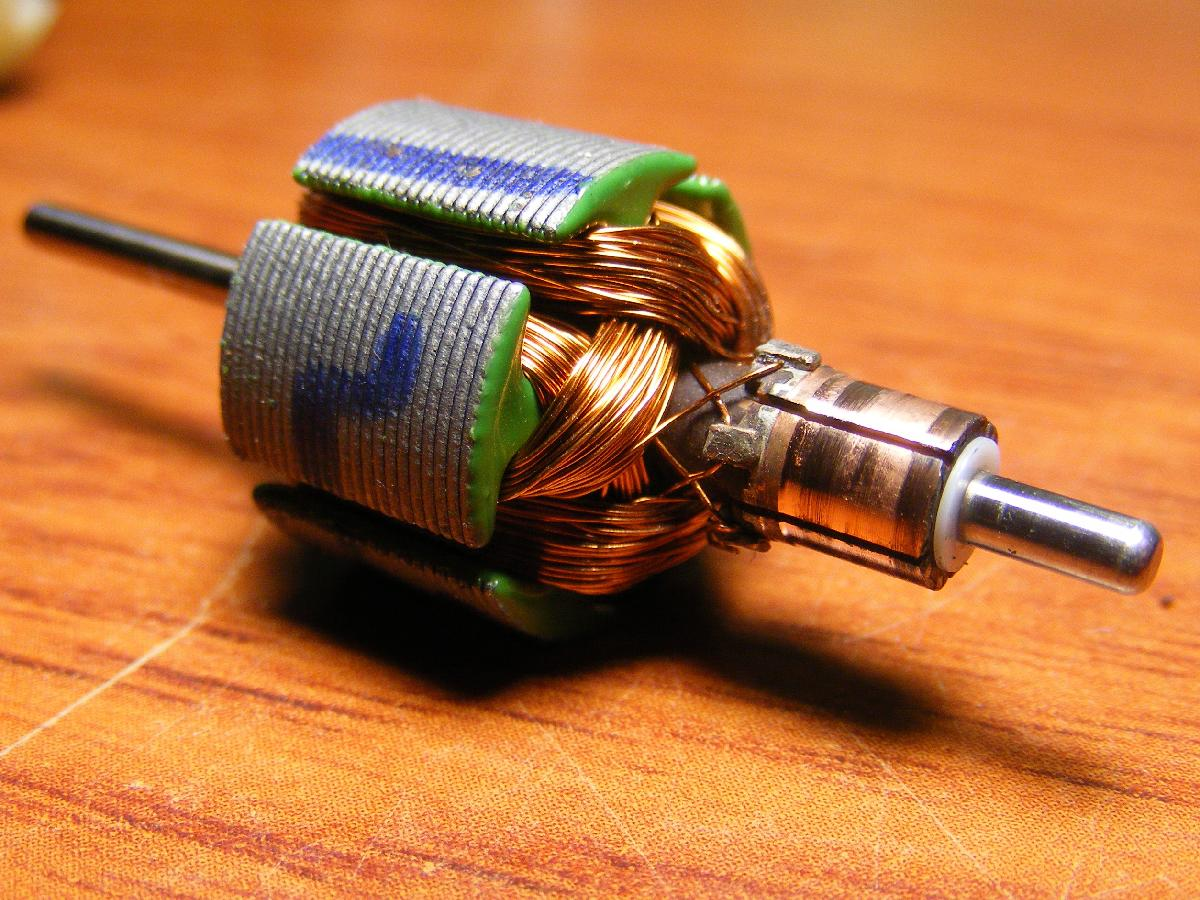

A small DC motor rotor (Source: Wkimedia)

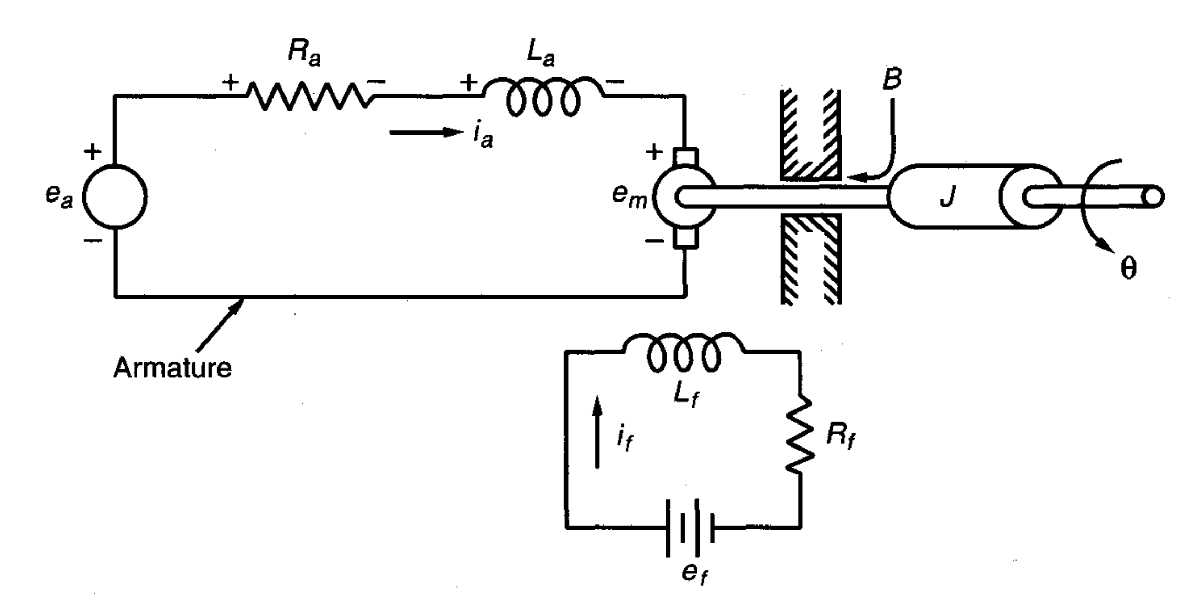

A simplified model of an armature voltage-controlled DC servomotor.

### Hypotheses of the DC servomotor model:

- The magnetic flux between the stator and the motor's rotor is kept constant for an armature-controlled DC motor. To this aim, either the stator voltage $e_f$ is constant (as in the picture above - please note, the current $i_f
$ is constant in this situation), or a permanent magnet replaces the stator coils. 

- From now on, we disregard the detailed description of the stator circuit, retaining only the assumption that the magnetic flux between the stator and rotor is constant.

### The model


$$\[
 \left\{ 
\begin{array}{rcl}
  \left[\begin{array}{c} \dot{x}_1 \\ \dot{x}_2 \\ \dot{x}_3 \end{array} \right]&=& 
	 \left[ \begin{array}{ccc}
		0 & 1 & 0  \\[1 em]
		0 & \displaystyle -\frac{B}{J}  & \displaystyle \frac{K_T}{J}  \\[1 em]
		0 & \displaystyle -\frac{K_{\vartheta}}{L_a}  &-\frac{R_a}{L_a}
		\end{array} \right]  \cdot  \left[\begin{array}{c} x_1 \\ x_2 \\ x_3 \end{array}\right] + 
		 \left[\begin{array}{c} 0  \\[1 em] 0 \\[1 em] \displaystyle\frac{1}{L_a}  \end{array} \right]
									\cdot u \\[2 ex]\\
		 \left[\begin{array}{c} y_1 \\ y_2  \end{array} \right] &=& 
			\left[\begin{array}{ccc}
				1 & 0 & 0  \\[1 em]
				0 & 1 & 0 
			\end{array} \right] \cdot \left[\begin{array}{c} x_1 \\ x_2 \\ x_3 \end{array} \right] 
\end{array}  \right.
\]
$$


Parameters:

- the resistance of the armature windings $R_a$;

- the armature winding inductance $L_a$;

- the viscous damping due to bearing friction $B$;

- the moment of inertia of the armature and load $J$;

- the torque constant $K_T$;

- the back-emf voltage constant $K_{\vartheta}$.

Input:

- externally applied armature voltage $e_a$

Outputs:

- the shaft positiion $\vartheta$;

- the shaft angular velocity $\dot{\vartheta}$;

State variables:

- the shaft positiion $\vartheta$;

- the shaft angular velocity $\dot{\vartheta}$;

- the armature current $i_a$;


$$\left\{
\begin{array}{rcl}
	x_1(t) &=&  \vartheta(t) \\
	x_2(t) &=&  \dot{\vartheta}(t) \\
	x_3(t) &=& i_a(t)\\
	u(t) &=& e_a(t)\\
	y_1(t) &=& x_1(t) \\
	y_2(t) &=& x_2(t)
\end{array} \right.$$


### Reference

- Antsaklis  P. J.  & Michel  A. N. (2006). *Linear systems*. Birkhäuser.

### Initialisation 

% cleaning the Matlab workspace

close all
clear
clc

% and assigning the parameters for the DC motor model
% 
Ra = 2.0;       % [Ohm] the resistance of the armature winding 
La = 0.5;       % [H] the armature winding inductance
J  = 1;       % [kg m^2] the moment of inertia of the armature and load
B  = 4;       % [N m s] the viscous damping
    K_T = 3.5;  % [N/A] the torque constant 
K_theta = 2.0;  % [N s] the back-emf voltage constant

### The continuouus-time LTI system

% the matrices of the LTI system equations
matA_DC = [ 0        1          0   ;...
         0       -B/J      K_T/J ;...
         0   -K_theta/La  -Ra/La];
       
matB_DC = [ 0 ;...
         0 ;...
         1/La  ];  
       
matC_DC = [1 0 0 ;...
        0 1 0 ];
          
matD_DC = [0; 0];

% let's create a continuous-time LTI system
LTI_DCmotor = ss(matA_DC, matB_DC, matC_DC, matD_DC);

eig(matA_DC) % the eigenvalues: they compare in the response modes of the free state movement

There are one real null eigenvalue and the others are conjugate complexes. If we consider the free state movement of the continuous time LTI system, the response modes contain a constant mode and two damped **sinusoids** with an angular frequency  $\bar{\Omega} \approx 3.7417\; \text{rad/s}$, i.e. with the period $\bar T \approx 1.6792 \; \text{s}$.

### Sampling the LTI system

Let's get a few **sampled time descriptions** of this LTI dynamic system. 

To explore the effects of sampling, we choose two different sampling periods: the first of relatively small value ( $T_1 \ll \bar T$ ) and the other one close to the free movement sinusoid period. Using each of them, we discretise the system, obtaining two sampled-time representations of the system. Evaluate the forced response to a unit step input (applied to both the inputs) of these discrete-time models, then compare the results with the outputs of the continuous-time model. 

% 1st sampling experiment
%
Ts1DC = 1/10; % [s] - 20 samples per second

sysD1_DC = c2d(LTI_DCmotor,Ts1DC); % <-- let's convert from continuous-time to sampled time LTI system
Ad1_DC=sysD1_DC.A; Bd1_DC=sysD1_DC.B;
Cd1_DC=sysD1_DC.C; Dd1=sysD1_DC.D;
format long
eig(Ad1_DC) % the eigenvalues of the sampled system
format short


Compare the eigenvalues with those of the continuous-time system: again, there are one real eigenvalue and two conjugate complexes, associated with damped oscillations.

% 2nd sampling experiment
%
Ts2DC = 2.0; % [s]  very close to the period of the free state movement oscillations - 1 sample every 2.0 seconds (0.5 sample per second)
sysD2_DC = c2d(LTI_DCmotor,Ts2DC); % <-- let's convert from continuous-time to sampled time LTI system
Ad2_DC=sysD2_DC.A; Bd2_DC=sysD2_DC.B;
Cd2_DC=sysD2_DC.C; Dd2_DC=sysD2_DC.D;
format long
eig(Ad2_DC) % the eigenvalues of the 2nd sampled system
format short

If we compare this result with that obtained from the previous sampled-time description of the system, we note that the response modes with damped oscillations are present. However, the period of the oscillations is more significant than that obtained in the first example. 

### Graphical Comparison of the Step Responses

To better understand what happens when changing the sampling period, let us compare the unit step responses of the continuous-time system with those of the sampled-time representations.

% --- step input configuration ---
%
% input <-- armature voltage [V] <--> an increment of 1 V
%
opt = stepDataOptions('StepAmplitude',1.0);
% ----------------------------------


% --- final time instant fo the step uoutputs evaluation
Tfinal = 4.5; % s

% --- step outputs evaluation ---
[Yc, Tc] = step(LTI_DCmotor, Tfinal, opt);
[Yd1, Td1] = step(sysD1_DC, Tfinal, opt);
[Yd2, Td2] = step(sysD2_DC, Tfinal, opt);

lineStyles = zeros(3,3);
lineStyles(1,:) = [0 0.4470 0.7410];
lineStyles(2,:) = [0.8500 0.3250 0.0980];
lineStyles(3,:) = [0 1 0];
% three different plot colors [as RGB triplet]

% ------------------------------------------------------------
f_DC = figure('Name','armature controlled DC motor - step response', ...
         'Units','normalized', 'Position', [0, 0, 0.80, 0.90]);

subplot(1,2,1); % <-- from input u1 to output y1
plot(Tc, Yc(:,1,1),'-','Color',lineStyles(1,:),'LineWidth',2.0); 
% the continuous-time step output 
hold on;
plot(Td1,Yd1(:,1,1), 'LineStyle','none', 'Marker','diamond',...
    'MarkerSize',6.0, 'MarkerFaceColor',lineStyles(2,:),...
    'MarkerEdgeColor',lineStyles(2,:)); % step response of the 1st discrete time model
plot(Td2, Yd2(:,1,1),'LineStyle','none', 'Marker','square',...
    'MarkerSize',12.0, 'MarkerFaceColor',lineStyles(3,:),...
    'MarkerEdgeColor',lineStyles(3,:)); % step response of the 2nd discrete time model 
% --- set the X axis limits
curr_ax = axis;
curr_ax(1)= curr_ax(1)-1e-1; curr_ax(2)= Tfinal; 
axis(curr_ax);
% ---
title('From $u$ to $y_1$', 'Interpreter','latex');
xlabel('Time [s]', 'Interpreter','latex'); 
ylabel('$y_1$', 'Interpreter','latex');
grid on;
set(gca, 'FontSize', 16);
legend('continuous-time system',['sampling rate ',num2str(1/Ts1DC),...
        ' SPS'],['sampling rate ', num2str(1/Ts2DC), ' SPS'],...
        'Location','best');

subplot(1,2,2); % <-- from input u1 to output y2
plot(Tc, Yc(:,2,1),'Color',lineStyles(1,:),'LineWidth',2.0);
% the continuous-time step output 
hold on;
plot(Td1,Yd1(:,2,1),'LineStyle','none', 'Marker','diamond',...
    'MarkerSize',6.0, 'MarkerFaceColor',lineStyles(2,:),...
    'MarkerEdgeColor',lineStyles(2,:)); % step response of the 1st discrete time model
plot(Td2, Yd2(:,2,1),'LineStyle','none','Marker','square',...
    'MarkerSize',12.0, 'MarkerFaceColor',lineStyles(3,:),...
    'MarkerEdgeColor',lineStyles(3,:)); % step response of the 2nd discrete time model 
% --- set the X axis limits
curr_ax = axis;
curr_ax(1)= curr_ax(1)-1e-1; curr_ax(2)= Tfinal; 
axis(curr_ax);
% ---
title('From $u$ to $y_2$', 'Interpreter','latex');
xlabel('Time [s]', 'Interpreter','latex');  ylabel('$y_2$', 'Interpreter','latex');
grid on;
set(gca, 'FontSize', 16);
legend('continuous-time system',['sampling rate ',num2str(1/Ts1DC),...
        ' SPS'],['sampling rate ', num2str(1/Ts2DC), ' SPS'],...
        'Location','best');

### Remarks 

Using the larger sampling time, there is no way to reconstruct the transient response of the system. Moreover, the reconstructed responses appear way slower than the effective, continuous-time, responses. 

### Proposal

- Use different sampling time values and analyse the results: select a first sampling time shorter than 0.1 s and a different sampling period larger or equal to 2 s. 

- What happens to the step responses of the sampled systems? 

- Does the same kind of phenomenon still occur?

## Final Remarks

- by selecting different sampling rates we obtained different representations of the same continuous-time dynamic system

- sampling may heavily distort the information, giving a completely wrong discrete-time representation of the original continuous-time system!